clear all
close all
clc
beep off

load trace_psu.mat

tratto1=2;
tratto2=2;
tratto3=2;
tratto4=3;
colore1 = [0.25 0.25 0.25];
colore2 = [0.5 0.5 0.5];
colore3 = [0.75 0.75 0.75];
colore4 = [0 0 0];

fontsize_plotting = 12;

options = bodeoptions;
options.FreqUnits = 'Hz';

tc = 1/1.25e9;
N1 = 1000;
N2 = 1000;
N = length(i1);
time = [0:tc:(N-N1-N2)*tc];
i1 = i1(N1:N-N2);
i1 = i1 - mean(i1);
i1_rms_res = sqrt(mean(i1.^2))

i1_rms_res = 0.2906

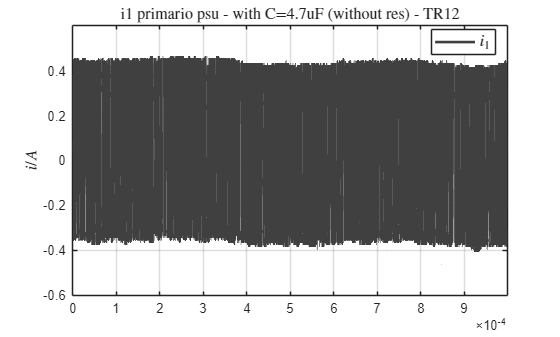

t1 = time(1);
t2 = time(end);

fig1 = figure; 
colors = [colore1; colore2];
colororder(colors)
plot(time, i1,'-','LineWidth',tratto1,'Color',colore1);
% set(gca,'ylim',[-1 1])
ylabel('$i/A$','Interpreter','latex','FontSize', fontsize_plotting);
title('i1 primario psu - with C=4.7uF (without res) - TR12','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_1$','Location','best',...
    'Interpreter','latex','FontSize',fontsize_plotting);
set(gca,'xlim',[t1 t2])
set(gca,'ylim',[-0.6 0.6])
grid on
fig1.PaperOrientation = "landscape";
print(fig1,'i1_current_comparison', '-dpdf','-fillpage');